# REST TASK REST

Long recording lasting 15 minutes. First 5 min: relax phase R1. Successive 5 min: task phase T (solving arithmetic operations and providing a solution choosing one out of three possible choices). Final 5 min: relax phase R2.

I apply ICA to all the recording, and after preprocessing I want to analyze the processed data. The analysis involves the alpha rhythm (8-13/14 Hz), which we know is dominant during the relaxig phase. I want to see how it changes during T and R2. During the relaxed condition alpha is dominant in the posterior region of the scalp. It has the function of inhibiting processing of external stimuli, in particular visual (visual cortex is located posteriorly) --> helps the subject to isolate from the external enviromìnment (INTERNAL ATTENTION mechanism).

Frequency domain analysis: I want to compute in each phase the PSD (using pwelch) of the 13 signals. Then I group the 13 electrodes in 3 macro regions of the scalp

- Frontal region (F3, F4)

- Temporocentral region (T7, C3, Cz, C4, T8)

- Parieto-occipital region (PO3, PO4, PO7, PO8, O1, O2)

And I average the PSD of the channels in each macro region, to obtain PSD_frontal, PSD_tempcentr, PSD_parietocc for each of the three phases!! Total of 9 values. To visually inspect the results I plot in a single subplot PSD_frontal for the three different phases, and same for tempcentr and parietocc in other two subplots. Expected result: peak around 10 Hz in R1 and R2 (more prominent in the posterior regions). The peak should be greatly attenuated during the task.

Finally I can compute the alpha power in each region and for each phase (9 values, integral of PSD in range 8-14 Hz using *trapz*). I can then plot those values.

### 1) Loading and plotting the data

clc; clear
load('REST_TASK_REST.mat')
[n,m] = size(X);
fs = srate;
save('X.mat', 'X')

Utils: indices of the channels

% Frontal
F3 = find(strcmp(ch_names,'F3'));
F4 = find(strcmp(ch_names,'F4'));

% Temporo-Central
T7 = find(strcmp(ch_names,'T7'));
C3 = find(strcmp(ch_names,'C3'));
Cz = find(strcmp(ch_names,'Cz'));
C4 = find(strcmp(ch_names,'C4'));
T8 = find(strcmp(ch_names,'T8'));

% Parieto-Occipital
PO3 = find(strcmp(ch_names,'PO3'));
PO4 = find(strcmp(ch_names,'PO4'));
PO7 = find(strcmp(ch_names,'PO7'));
PO8 = find(strcmp(ch_names,'PO8'));
O1 = find(strcmp(ch_names,'O1'));
O2 = find(strcmp(ch_names,'O2'));

### Plotting 30 seconds of the uncleaned EEG signal 

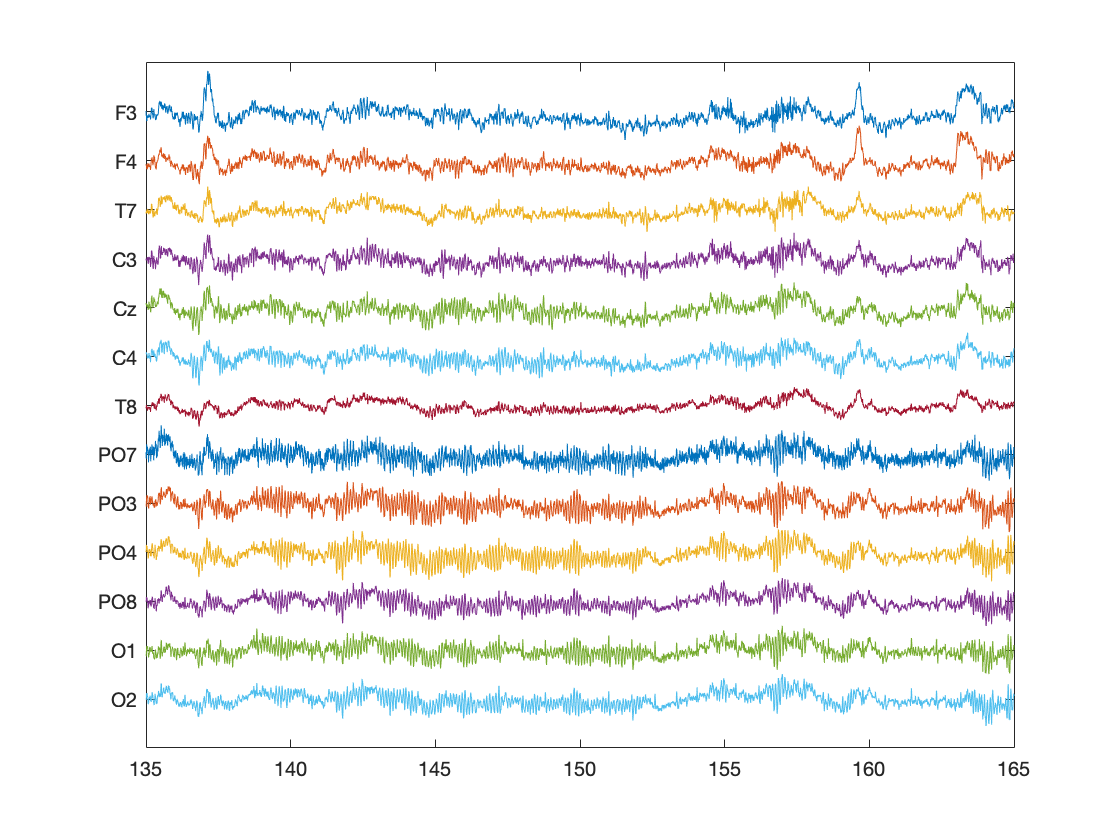

delta = 100;
X_samples = 1:m;
t = X_samples/fs; % time vector 
X_plot = X(:, 135*fs:165*fs);
figure
for i = 1:n % for every electrode
    plot(t(135*fs:165*fs), X_plot(i,:) - delta*(i-1))
    hold on
end
ylim([-delta*n, delta])
set(gca, 'ytick', [-delta*(n-1):delta:0])
set(gca, 'yticklabel', fliplr(ch_names))

### PSD of ICs

window = 5 * fs; % divide the signal in segments of 640 samples each.
NFFT = 2*window; % to increase frequency resolution
% Frequency res: fs/nfft = 0.1
% I except f to be 641 x 1
[PSD, f] = pwelch(X', window, [], NFFT, fs); % [] -> 50% overlap between segments
PSD = PSD';

 I now use EEGLAB to estimate the ICs and import both demixing matrix W and mixing matrix A (S = WX)

### 5) Plotting 30 seconds of the ICs  

load('W.txt') % demixing matrix
load('A.txt') % mixing matrix
S = W*X;

### 6) Plotting the PSD of the ICs

[PSD, f] = pwelch(S', window, [], NFFT, fs); %[] -> 50% overlap between segments
PSD = PSD';

max_frame = 115073

readlocs(): 'loc' format assumed from file extension


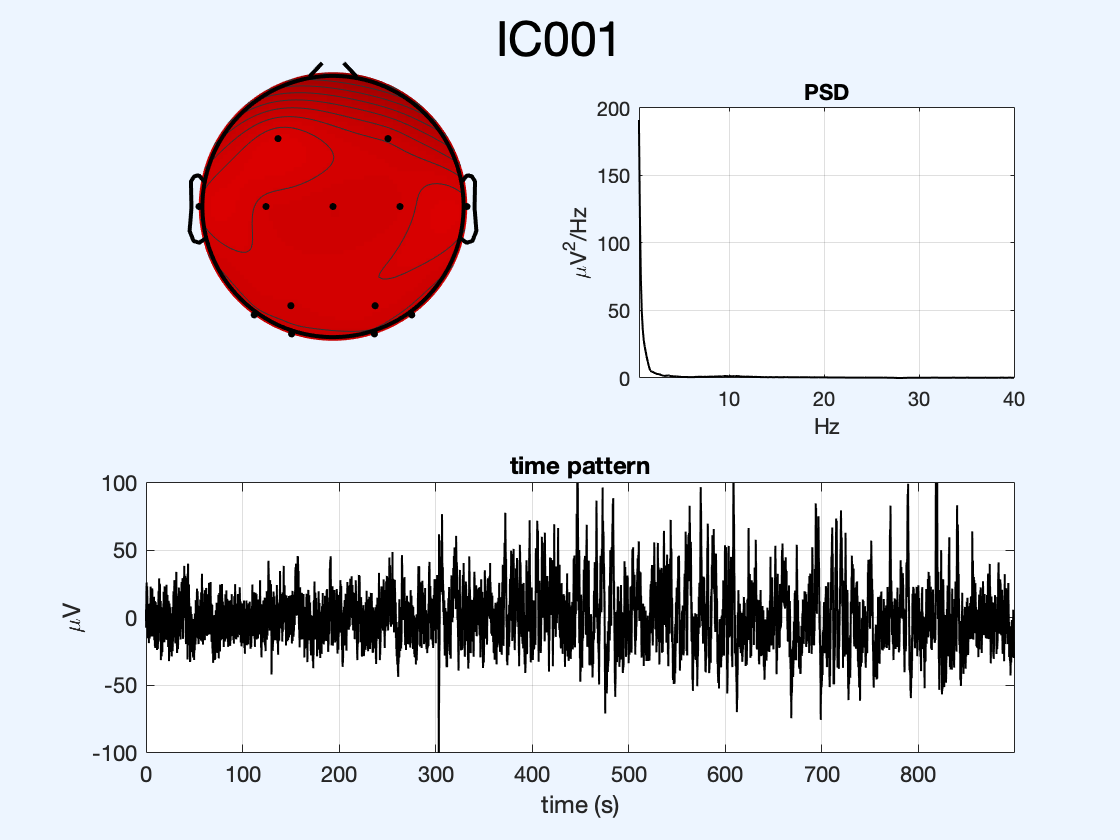

max_frame = 115073

readlocs(): 'loc' format assumed from file extension


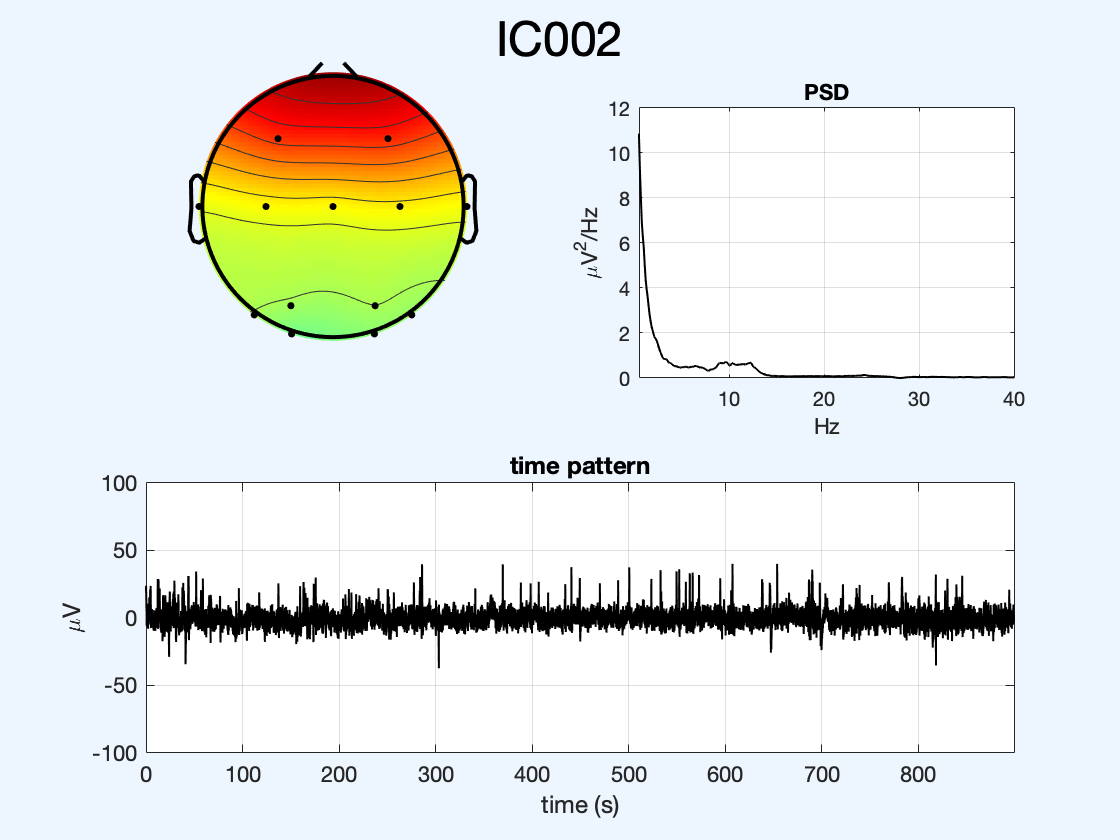

max_frame = 115073

readlocs(): 'loc' format assumed from file extension


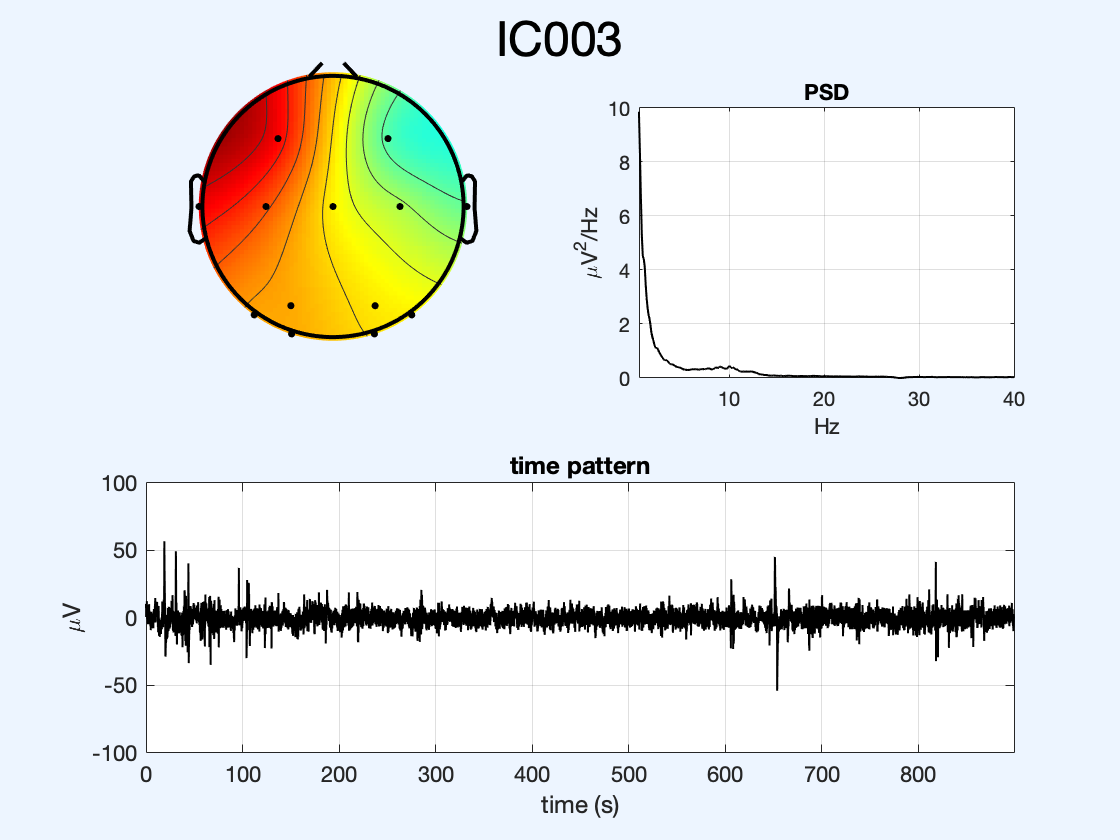

max_frame = 115073

readlocs(): 'loc' format assumed from file extension


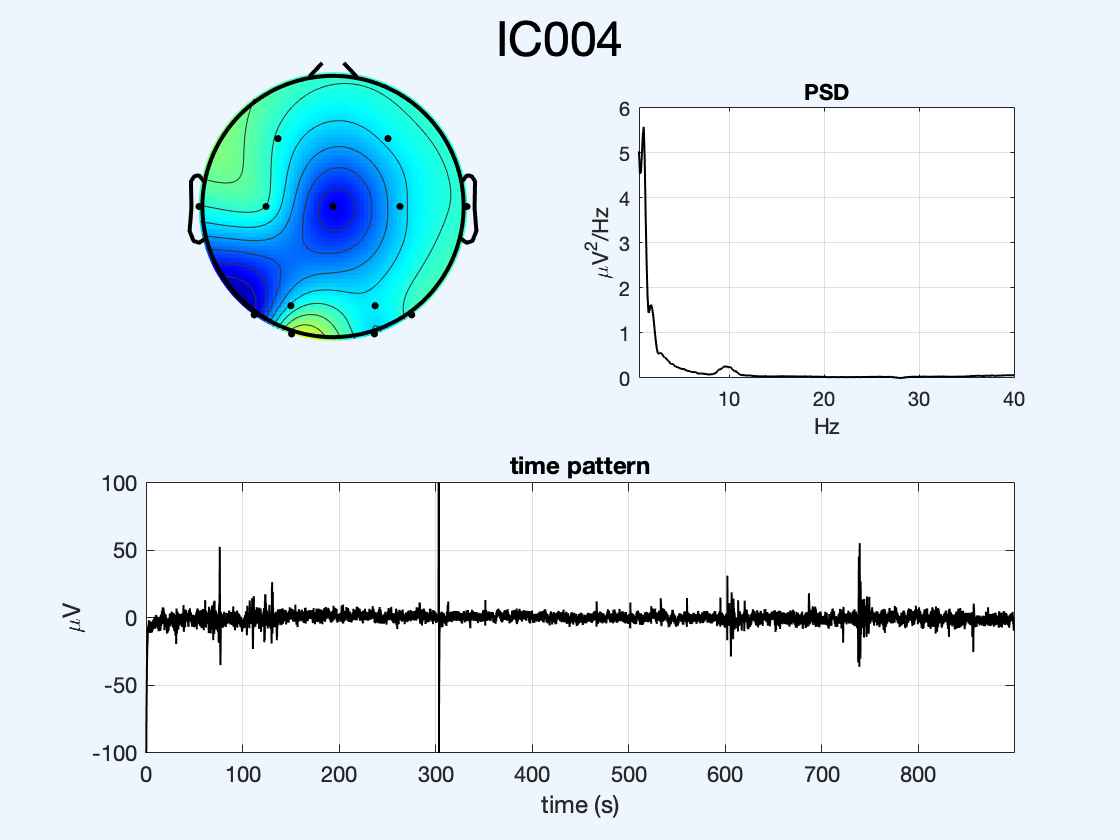

max_frame = 115073

readlocs(): 'loc' format assumed from file extension


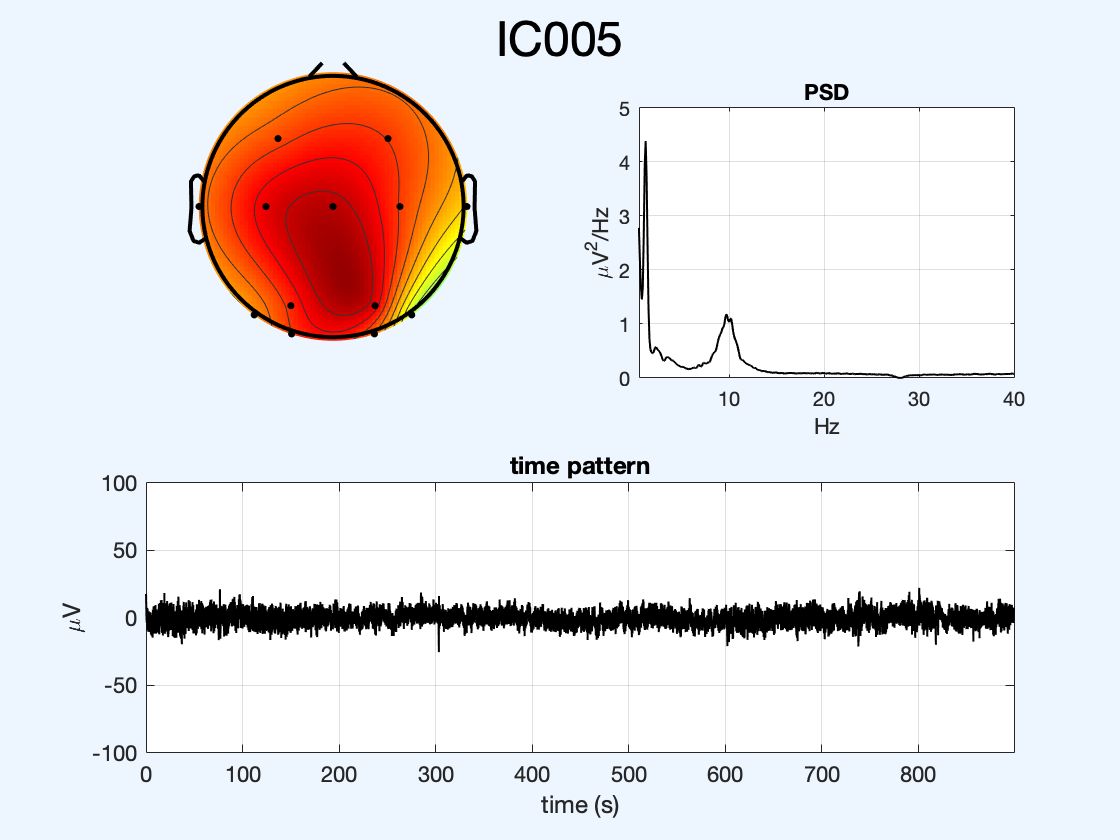

for i = 1:5
    figure
    plot_IC(i, A, S, PSD', f, 'Standard-10-20-Cap13.locs', fs, 0, 899);
end

IC1 ECG artifact + other slow artifacts (the subject moved during the recording?)

IC2 blinking artifact

IC3 lateral eye movement artifact

IC4 spectrum mainly limited to very low frequencies + large artifact as IC1 around 300 s

IC8 strange spectrum with high frequencies content and large artifact around 300 s

Also IC9, IC10 and IC11 seem to contain some artifact activity, but I have maintained them as they also contain alpha power

### 8) Reconstructing the EEG signals cleaned from artifacts

S_new = S; 
S_new([1,2,3,4,8], :) = 0; % putting to 0 the rows corresponding to the artifacts
X_new = A*S_new;  

Plotting the cleaned EEG signals in time (from 135s to 165s)

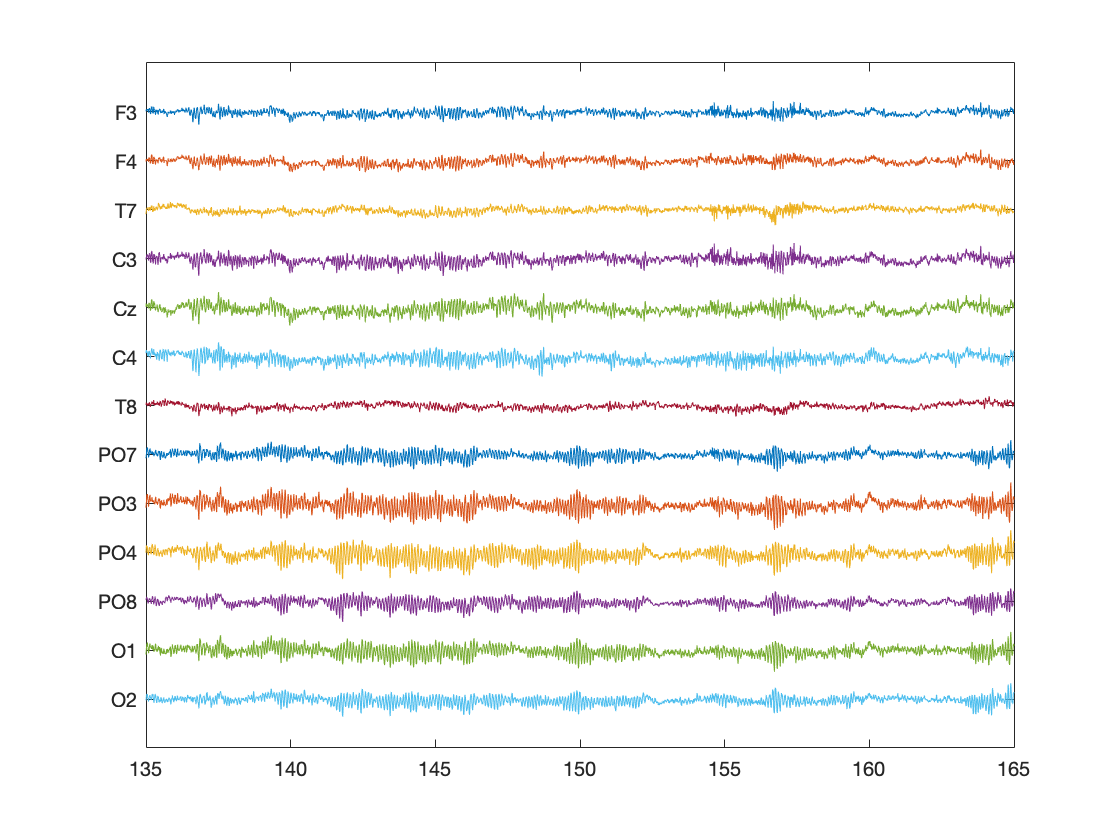

X_plot = X_new(:, 135*fs:165*fs);
figure
for i = 1:n % for every electrode
    plot(t(135*fs:165*fs), X_plot(i,:) - delta*(i-1))
    hold on
end
ylim([-delta*n, delta])
set(gca, 'ytick', [-delta*(n-1):delta:0])
set(gca, 'yticklabel', fliplr(ch_names))

### 9) Computing the PSD separately for the three phases (R1, T and R2)

X_R1 = X_new(:, 1:5*60*fs);
X_T = X_new(:, 5*60*fs+1:10*60*fs);
X_R2 = X_new(:, 10*60*fs+1:end);
% R1
[PSD_R1, f] = pwelch(X_R1', window, [], NFFT, fs); %[] -> 50% overlap between segments
PSD_R1 = PSD_R1';

% Task
[PSD_T, f] = pwelch(X_T', window, [], NFFT, fs); %[] -> 50% overlap between segments
PSD_T = PSD_T';

% R2
[PSD_R2, f] = pwelch(X_R2', window, [], NFFT, fs); %[] -> 50% overlap between segments
PSD_R2 = PSD_R2';

By visually comparing the three phases, we can observe how during the task the occipital alpha power is much lower wrt the relax phases. In which relax phase is the alpha power higher? I can compute the mean peak of the power in the posterior electrodes (from PO7 to O2) to get some first insights 

mean_PSDpeak_R1 = mean(max(PSD_R1(PO7:O2, 8/0.1:14/0.1), [], 2))

mean_PSDpeak_R1 = 23.6372

mean_PSDpeak_R2 = mean(max(PSD_R2(PO7:O2, 8/0.1:14/0.1), [], 2))

mean_PSDpeak_R2 = 40.3728

We can see that the mean peak is higher in the R2 phase. Possible explanation: during R1 the subject knows that he will eventually be presented with a stimulus --> not completely relaxed as in R2

### 10) Averaging the PSD between the electrodes belonging to each macro-region for each task 

- R1 

% Frontal
PSD_R1_TC = mean([PSD_R1(T7,:); PSD_R1(C3,:); PSD_R1(Cz,:); PSD_R1(C4,:); PSD_R1(T8,:)]);

% Temporo-Central
PSD_R1_F = mean([PSD_R1(F3,:); PSD_R1(F3,:)]);

% Parieto-Occipital
PSD_R1_PO = mean([PSD_R1(PO3,:); PSD_R1(PO4,:); PSD_R1(PO7,:); PSD_R1(PO8,:); PSD_R1(01,:); PSD_R1(01,:)]);

- TASK

% Frontal
PSD_task_F = mean([PSD_T(F3,:); PSD_T(F3,:)]);

% Temporo-Central
PSD_task_TC = mean([PSD_T(T7,:); PSD_T(C3,:); PSD_T(Cz,:); PSD_T(C4,:); PSD_T(T8,:)]);

% Parieto-Occipital
PSD_task_PO = mean([PSD_T(PO3,:); PSD_T(PO4,:); PSD_T(PO7,:); PSD_T(PO8,:); PSD_T(01,:); PSD_T(01,:)]);

- R2

% Frontal
PSD_R2_F = mean([PSD_R2(F3,:); PSD_R2(F3,:)]);

% Temporo-Central
PSD_R2_TC = mean([PSD_R2(T7,:); PSD_R2(C3,:); PSD_R2(Cz,:); PSD_R2(C4,:); PSD_R2(T8,:)]);

% Parieto-Occipital
PSD_R2_PO = mean([PSD_R2(PO3,:); PSD_R2(PO4,:); PSD_R2(PO7,:); PSD_R2(PO8,:); PSD_R2(01,:); PSD_R2(01,:)]);

Plotting the frontal PSD for each of the three phases

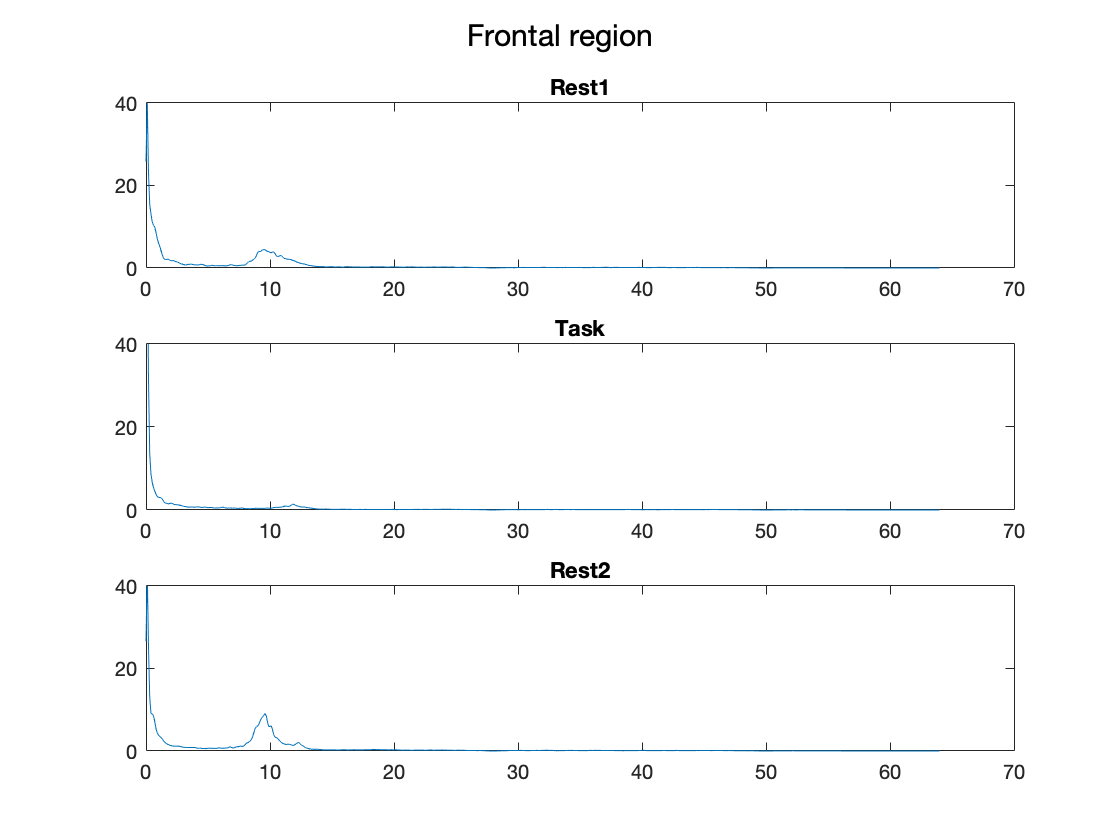

% 
figure
subplot(311)
plot(f, PSD_R1_F)
ylim([0 40])
title('Rest1')
subplot(312)
plot(f, PSD_task_F)
ylim([0 40])
title('Task')
subplot(313)
plot(f, PSD_R2_F)
ylim([0 40])
title('Rest2')
sgtitle('Frontal region')

Frontal: low alpha activity during R1 and R2, but still higher wrt to the task in all three regions

Temporal-Central

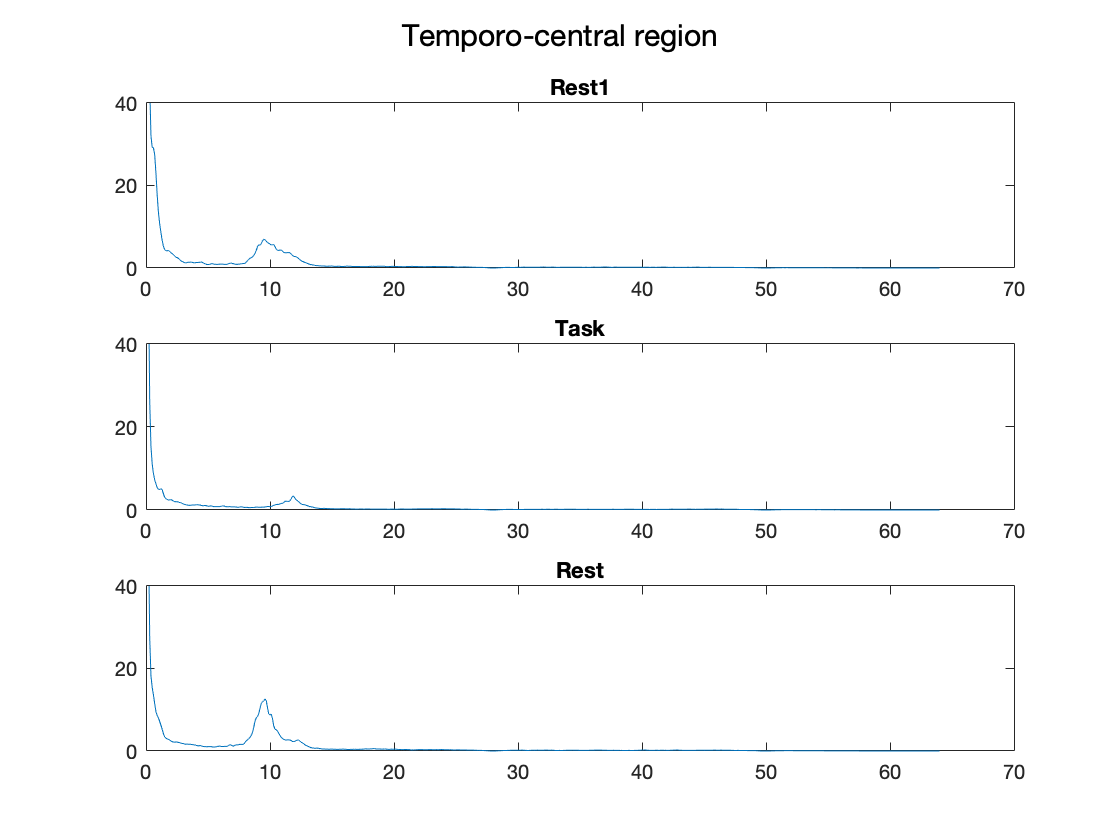

% Plotting the frontal PSD for each of the three phases
figure
subplot(311)
plot(f, PSD_R1_TC)
ylim([0 40])
title('Rest1')
subplot(312)
plot(f, PSD_task_TC)
ylim([0 40])
title('Task')
subplot(313)
plot(f, PSD_R2_TC)
ylim([0 40])
title('Rest')
sgtitle('Temporo-central region')

Temporal-central --> higher alpha band activity than frontal but still much lower than posterior

Parietal-Occipital

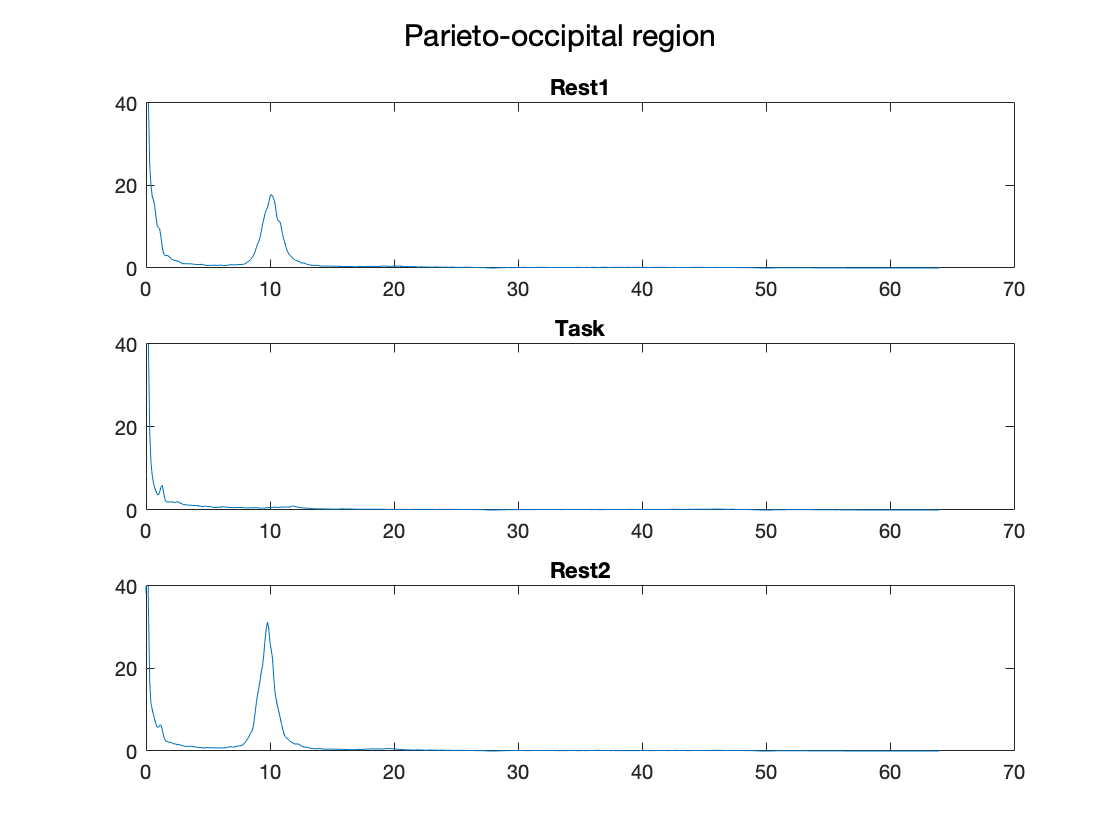

figure
subplot(311)
plot(f, PSD_R1_PO)
ylim([0 40])
title('Rest1')
subplot(312)
plot(f, PSD_task_PO)
ylim([0 40])
title('Task')
subplot(313)
plot(f, PSD_R2_PO)
ylim([0 40])
title('Rest2')
sgtitle('Parieto-occipital region')

Posterior electrodes: highest alpha activity in R1 and R2.

We can observe that for all three regions the alpha activity is greatly attenuated during the task

### 11) Computing the area of the PSD in the alpha band (alpha power) for each scalp region 

imin = find(f==8);
imax = find(f==14);

Frontal

% R1
alpha_pow_R1_F = trapz(f(imin:imax), PSD_R1_F(:, imin:imax));

% T
alpha_pow_T_F = trapz(f(imin:imax), PSD_task_F(:, imin:imax));

% R2
alpha_pow_R2_F = trapz(f(imin:imax), PSD_R2_F(:, imin:imax));

- Temporo-central

% R1
alpha_pow_R1_TC = trapz(f(imin:imax), PSD_R1_TC(:, imin:imax));

% T
alpha_pow_T_TC = trapz(f(imin:imax), PSD_task_TC(:, imin:imax));

% R2
alpha_pow_R2_TC = trapz(f(imin:imax), PSD_R2_TC(:, imin:imax));

- Parieto-occipital

% R1
alpha_pow_R1_PO = trapz(f(imin:imax), PSD_R1_PO(:, imin:imax));

% T
alpha_pow_T_PO = trapz(f(imin:imax), PSD_task_PO(:, imin:imax));

% R2
alpha_pow_R2_PO = trapz(f(imin:imax), PSD_R2_PO(:, imin:imax));

Summary plot

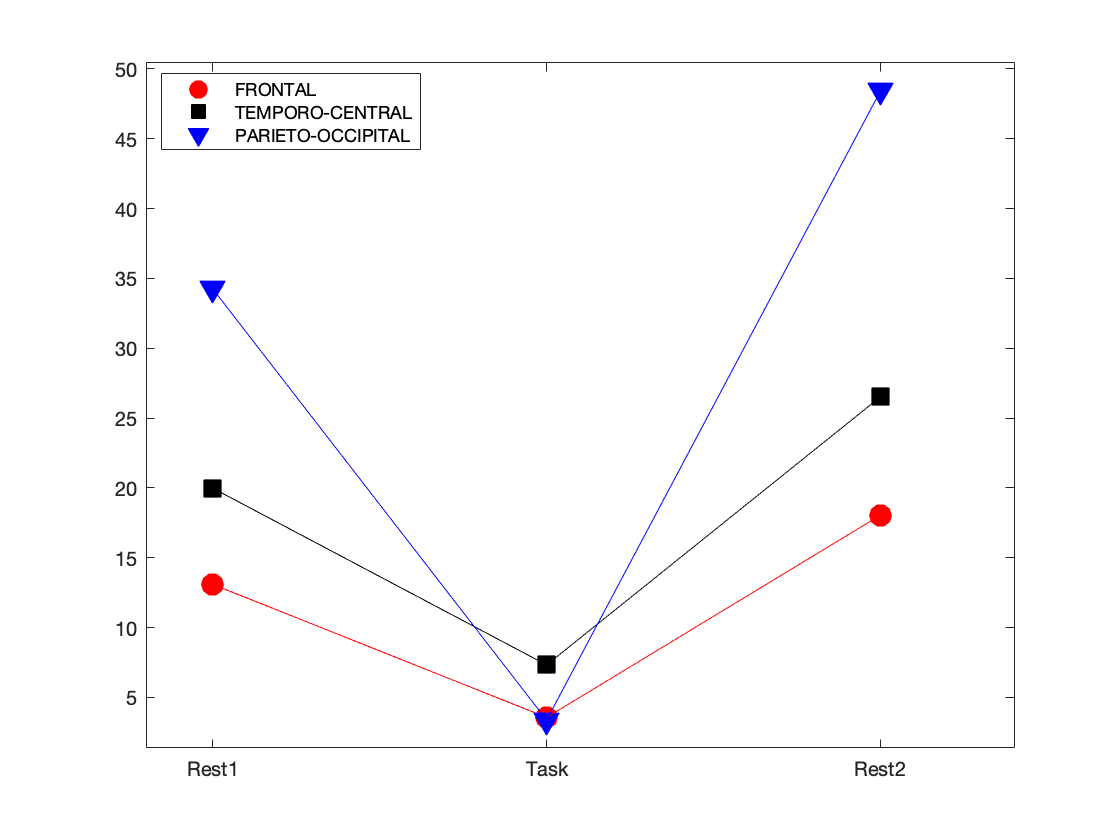

alpha_pow_R1 = [alpha_pow_R1_F, alpha_pow_R1_TC, alpha_pow_R1_PO];

alpha_pow_T = [alpha_pow_T_F, alpha_pow_T_TC, alpha_pow_T_PO];

alpha_pow_R2 = [alpha_pow_R2_F, alpha_pow_R2_TC, alpha_pow_R2_PO];

markers = ['ro'; 'ks'; 'bv']; 

figure
for i = 1:3
plot(1,alpha_pow_R1(i), markers(i,:), 'MarkerSize', 11, 'MarkerFaceColor', markers(i,1)); 
hold on
end

legend('FRONTAL', 'TEMPORO-CENTRAL', 'PARIETO-OCCIPITAL', 'AutoUpdate', 'off', 'Location', 'best')

for i = 1:3
plot(2,alpha_pow_T(i), markers(i,:), 'MarkerSize', 11, 'MarkerFaceColor', markers(i,1)); 
plot([1 2], [alpha_pow_R1(i) alpha_pow_T(i)], markers(i,1))
end

for i = 1:3
plot(3,alpha_pow_R2(i), markers(i,:), 'MarkerSize', 11, 'MarkerFaceColor', markers(i,1)); 
plot([2 3], [alpha_pow_T(i) alpha_pow_R2(i)], markers(i,1))
end

xticks([1 2 3])
xticklabels({'Rest1', 'Task', 'Rest2'})
xlim([0.8 3.4])
ylim([min(alpha_pow_T)-2 max(alpha_pow_R2)+2])
hold off